% add path to functions/scripts
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\KC_thresh_functions

% MANUALLY navigate to widefield/date_animalID folder


% load maps file for recording session (maps file generated by dfofMovie)
[df,frameT] = loadStage2MapsVars();

sizeDf =          208         255       37711


sizeFrameT =            1       37711


% load stimulus session data (comes from ballData folder on stimulus presentation computer)
[subjData,sessionFile,allStop,allResp,stimDetails,trialCond] = loadStage2subjSessVars();

% create figure title info
[date,subjName] = createTitleInfo(sessionFile,subjData);

date = 08 19 2021 

subjName = G6H305RT

numImagingFrames =        37711


percentSlippedImagingFrames =        2.8958


numMonitorFrames =       223234


percentSlippedMonitorFrames =        16.999


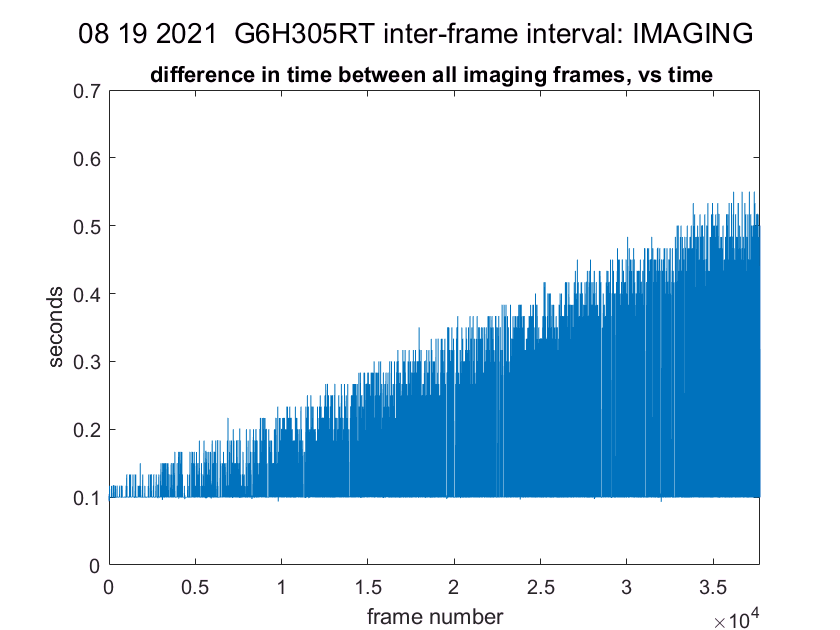

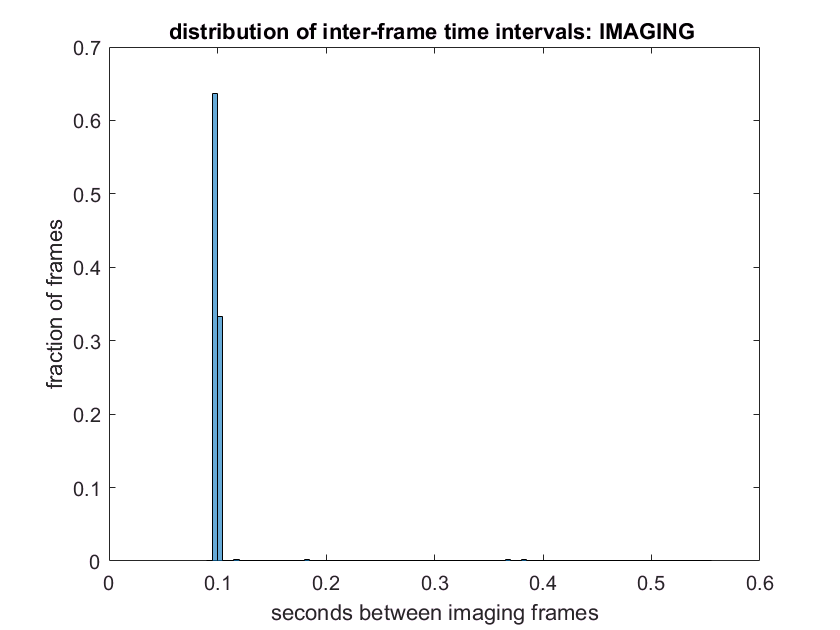

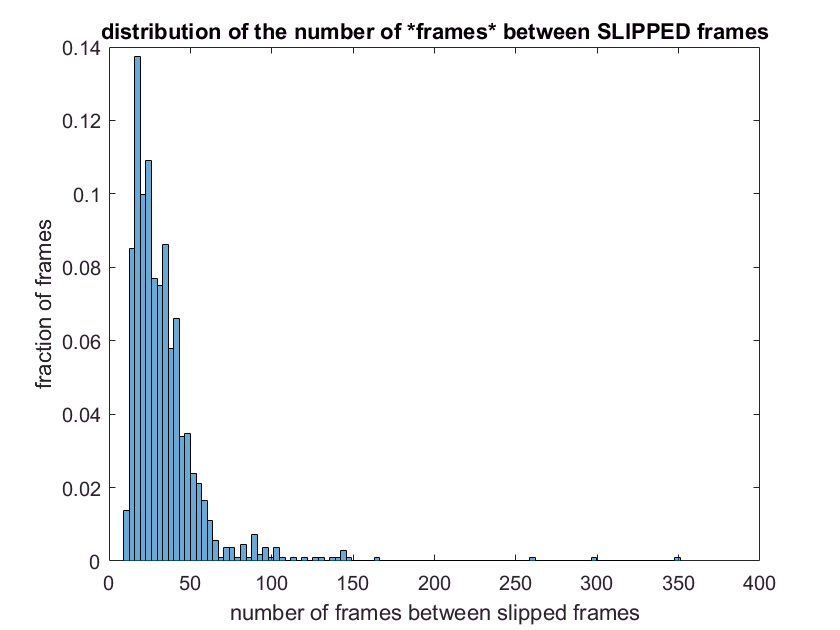

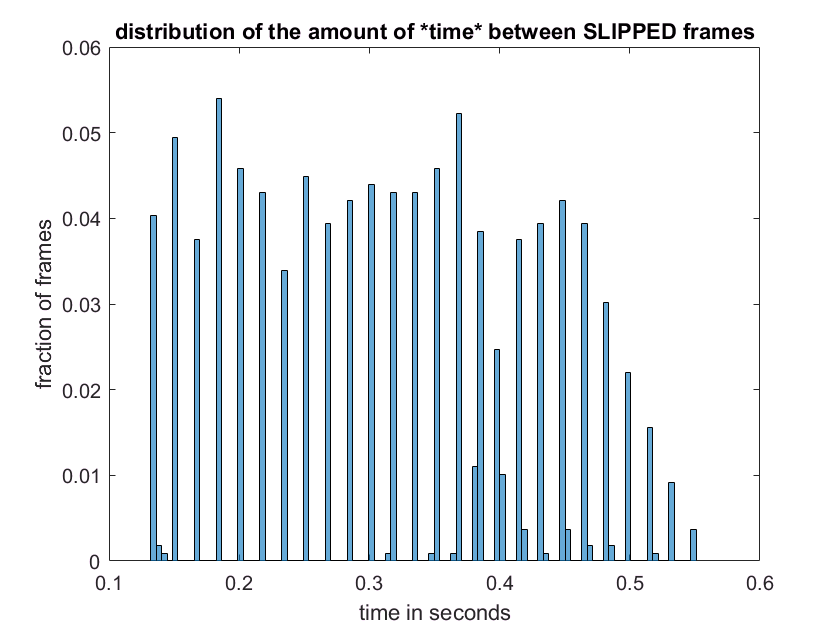

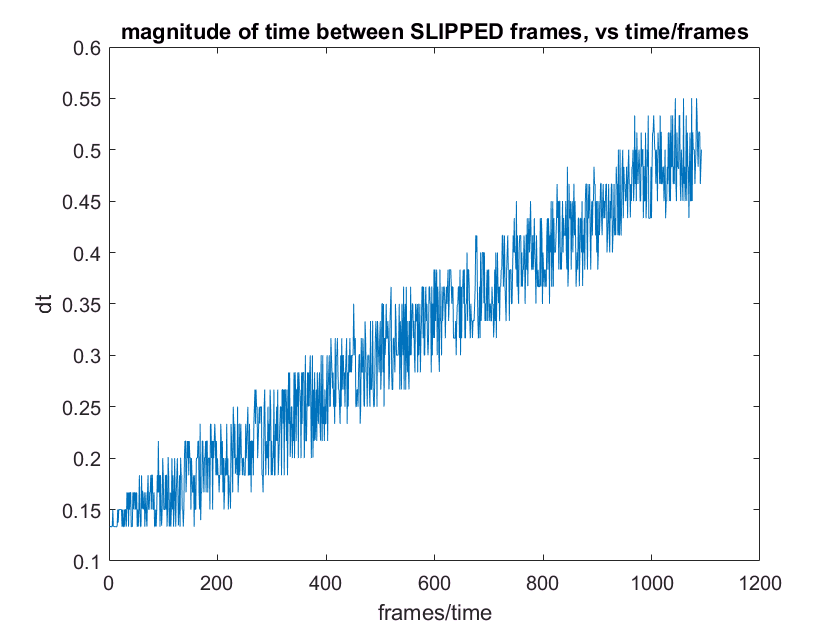

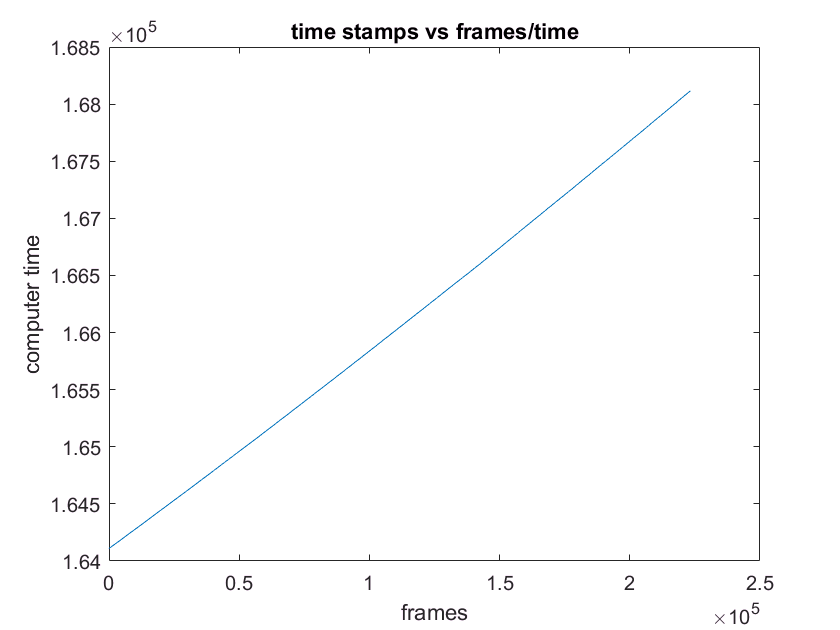

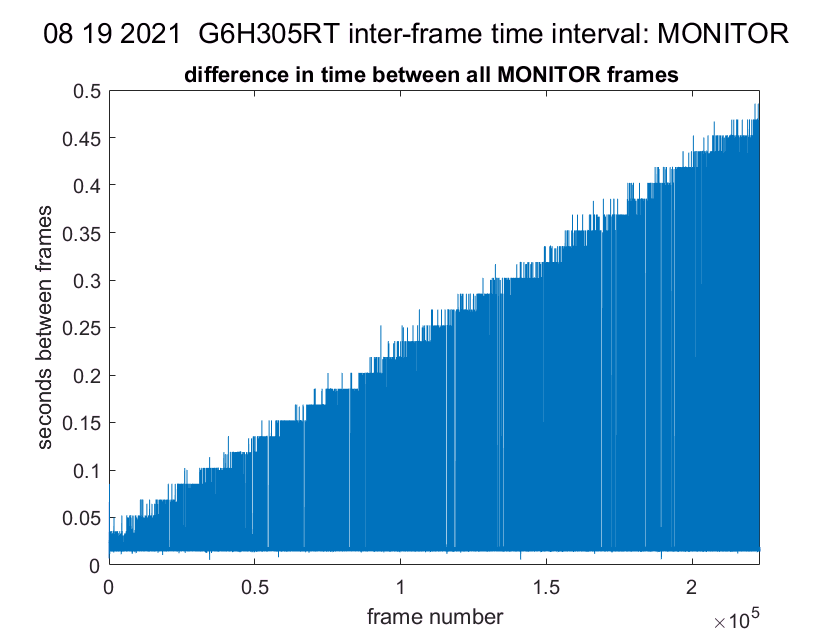

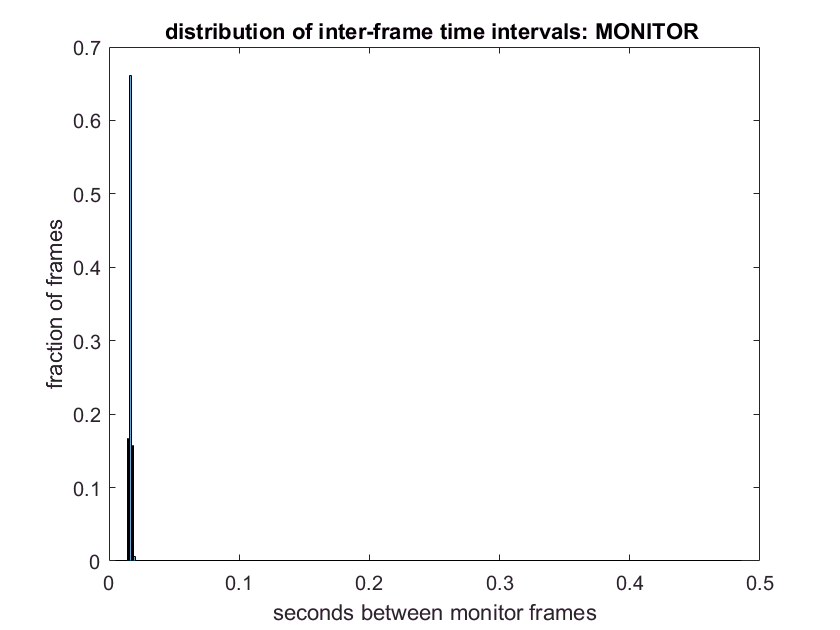

% check imaging & monitor frame rate
[percentSlippedImagingFrames,timeStampsStopAndRespFramesAlltrialsMinusT0,percentSlippedMonitorFrames] = checkImagingAndMonitorFrames(frameT,allStop,allResp,subjName,date);

sizeOf_allXYcursorCoordinatesStopAndRespFramesAlltrials =            2      223235


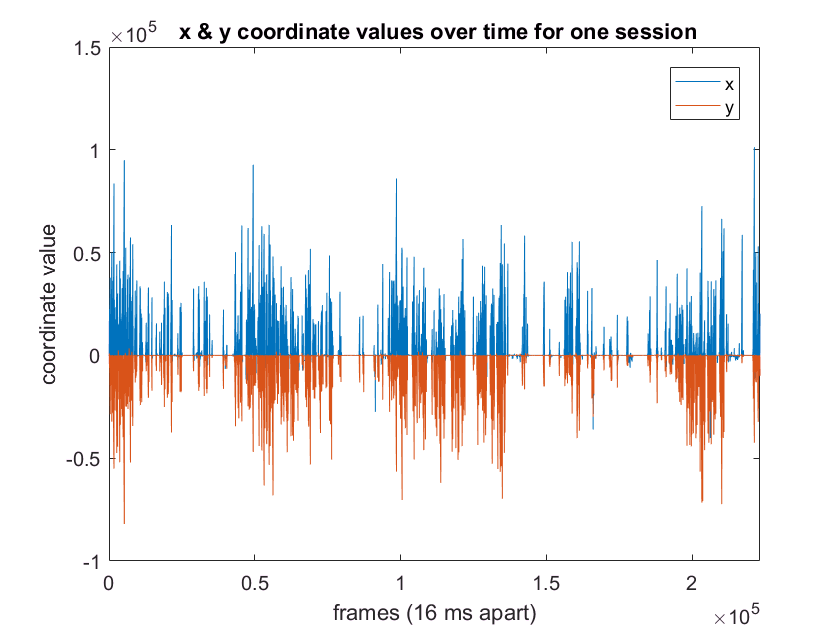

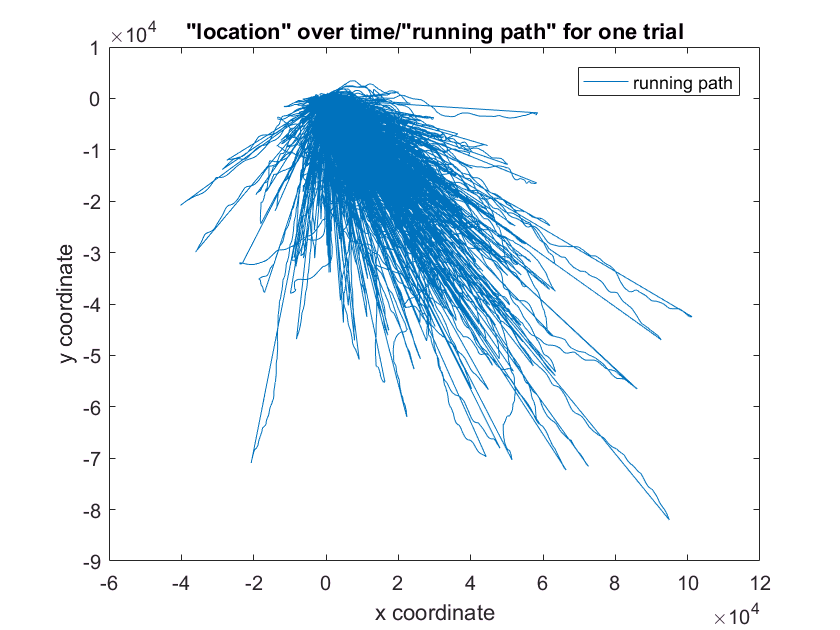

% 1st step running anlysis - x & y coordinates, run path
[allXYcursorCoordinatesStopAndRespFramesAlltrials] = stitchBackCursorCoordinatesForAllTrialsAndFrames(allStop,allResp);

numTrialsInSession =         1239


sizeOf_meanSpeedAllTrials =            1        1239


numTrials =         1239


numBins =     10


runThresh =     60


numTrialsOverThresh =    595


percentTrialsOverThresh =        48.023


numStatTrials =    644


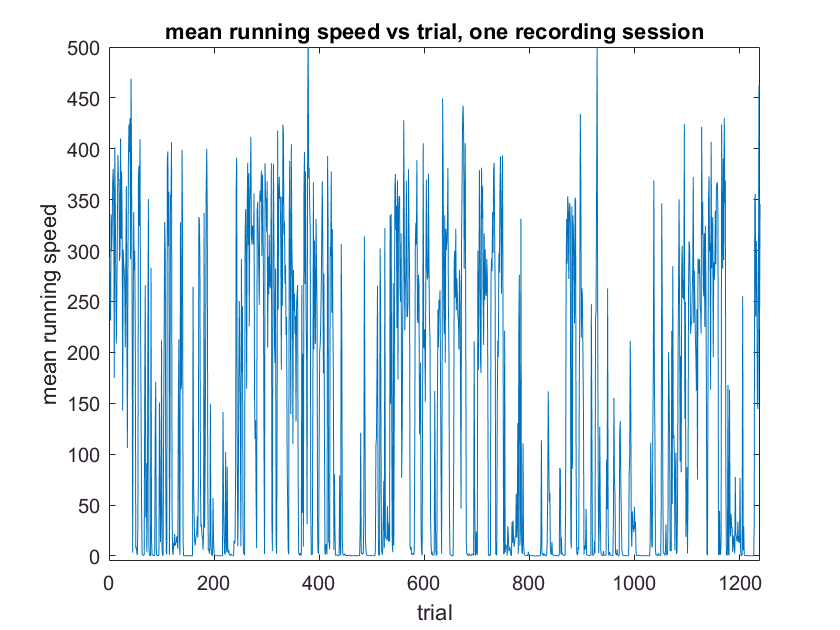

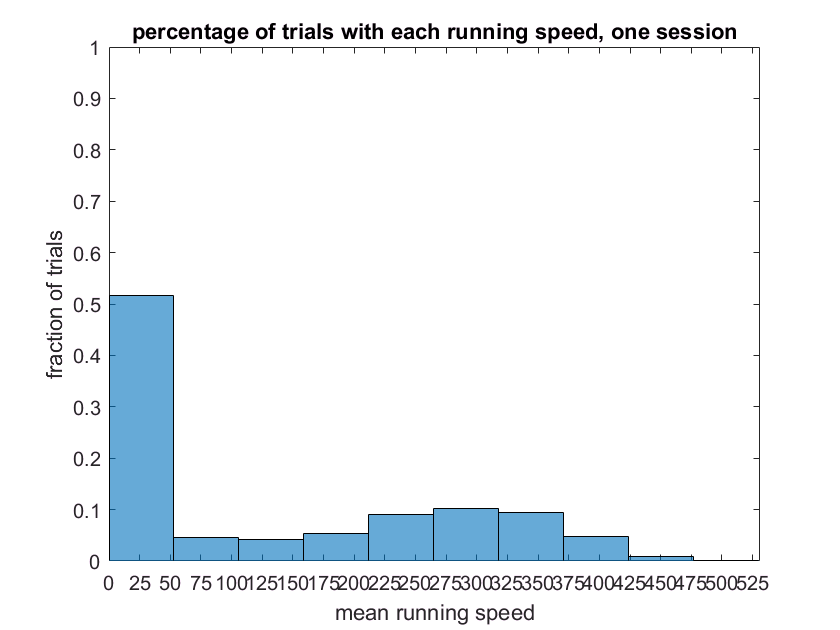

% calculate mean run speed for each trial
[meanSpeedAllTrials,idxRunTrials,idxStatTrials] = calcMeanRunSpeedAllTrials(allStop,allResp);

numFramesWholeSession =        37711


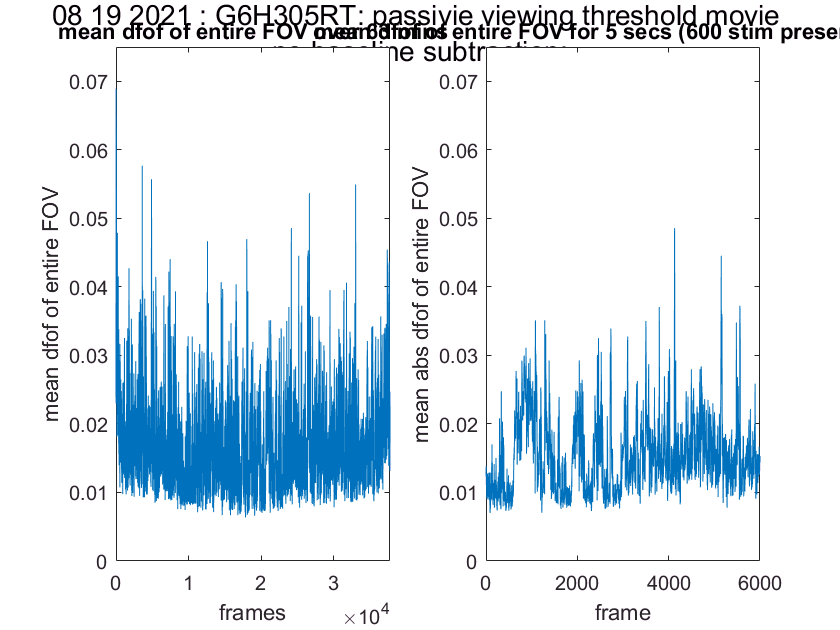

% 1st step imaging analysis - broad activity over whole field of view
meanDfEntireFOVvsFrames_wholeSessAnd1min(df,subjName,date);

range =             0         0.04


colorMapOrNot =      2


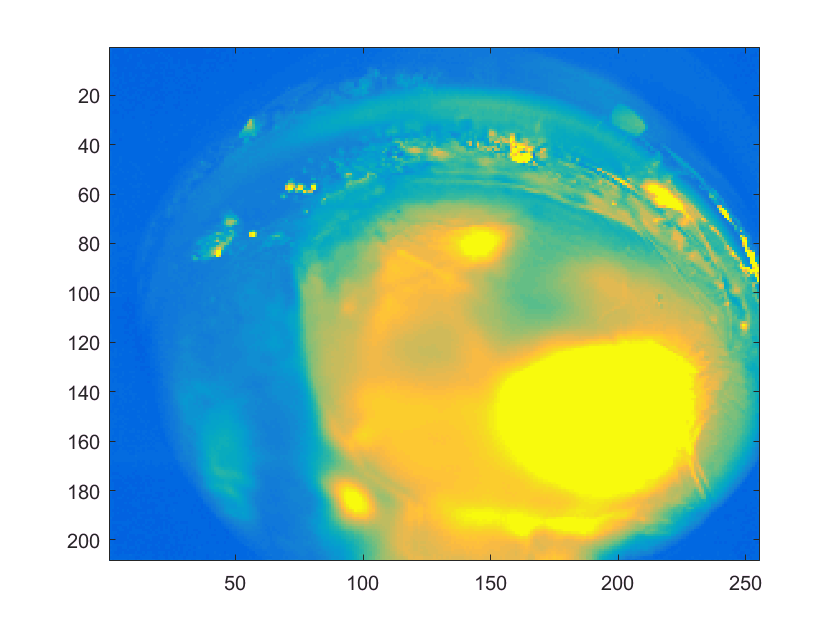

% pick the image/adjust the range on the image to be used for cropping in following step
[range,colorMapOrNot] = pickImageToCrop(df,subjName,date);

% need script code here that re-runs the above function, 
% continuing to adjust the range values, until the users says to move forward with cropping


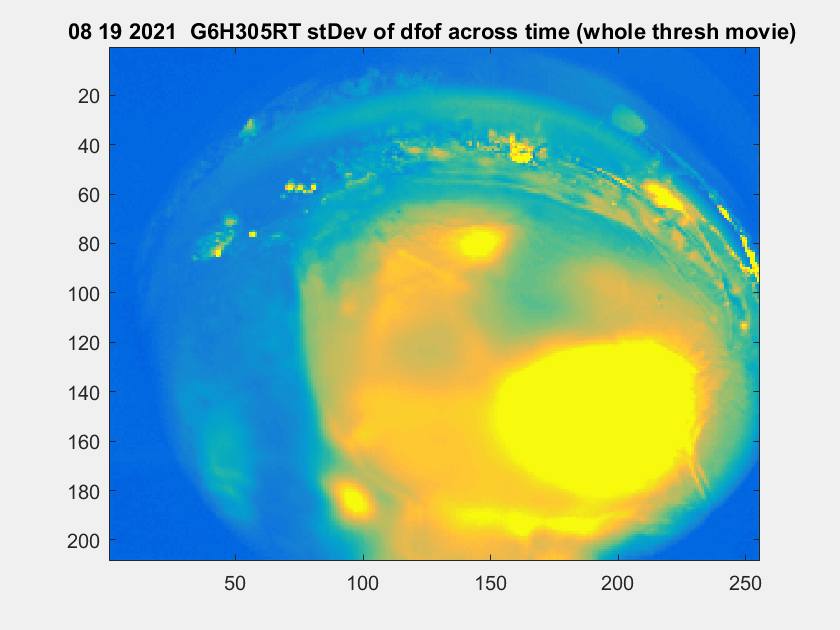

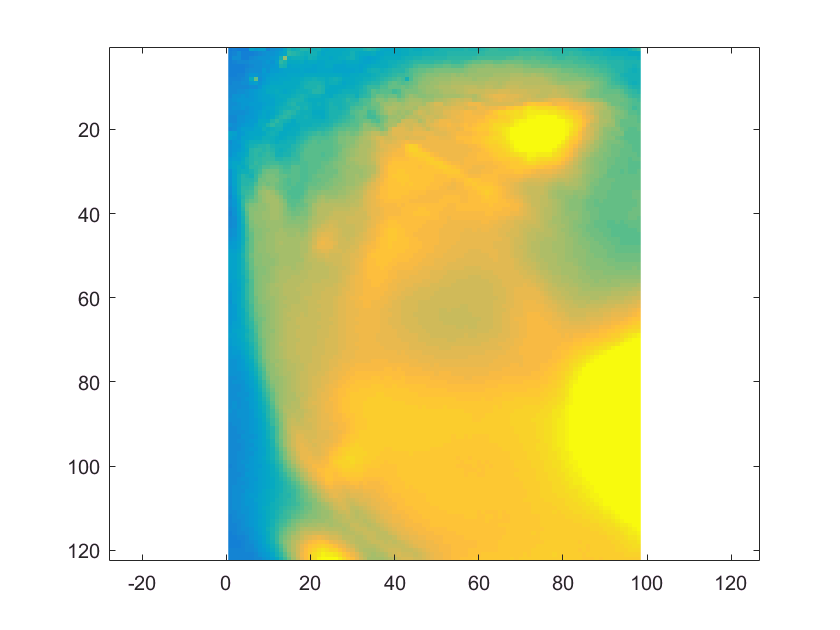

% crop image/movie & show cropped image
[xPtsCrop,yPtsCrop,dfCROP] = doCrop(df,range,colorMapOrNot,date,subjName);

% get time of stimulus onsets for each trial
[stimOnsets] = onsetsStimFrames(allStop,allResp);

sizeOfOnsets =            1        1239


% how many early & late trials to filter out? change this in this meta script if need
earliestTrial = 6

earliestTrial =      6


numLateTrialsSubtract = 5

numLateTrialsSubtract =      5


% filter first and last few trials... can change num trials in code
[idxOnsetsMeetsCriteria,filteredStimOnsets] = filterOnsets_removeEarlyAndLateTrials(stimOnsets,earliestTrial,numLateTrialsSubtract);

sizeOnsetsMeetCriteria =            1        1229


% for each trial, get the indicies for the 1st imaging frame that folows the stimulus onset
[onsetImFrames] = onsetImagingFrames(filteredStimOnsets,frameT);

sizeOfOnsetImFrames =            1        1229


% picking pre & post imaging frames for indexing dfCROP into "chunks"

% keeping this in the meta script for now b/c i want it easily changeable
% but will have next function display these values
numPreStimFrames = 3

numPreStimFrames =      3


numPostStimFrames = 14

numPostStimFrames =     14


% make onsetDf variable

% use the indicies for the 1st imaging frame follwing stimulus onset, 
% plus the num pre & post frames defined earlier in this script,
% to index into dF % take 'chunks' of video around each stim onset
[onsetDf] = makeOnsetDf(onsetImFrames,dfCROP,numPreStimFrames,numPostStimFrames);

sizeOfOnsetDf =          122          98          18        1229


% make vector of stim conditions in order of presentation/trial,
% & list of unique stim params (for looping)
[conOrderedByTrialMeetCriteria,uniqueContrasts,durOrderedByTrialMeetCriteria,uniqueDurations,conAndDurOrderedByTrialMeetCriteria] = getStimParamsNtrialConds(stimDetails,trialCond,idxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of flurescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);

% pick the baseline indicies, show the mean baseline image, subtract from pix wise onsetDf
% images to demonstrate that these baseline indicies are appropriate. Diagnostic figures. 

% % NEED DO IN COMMAND WINDOW/NOT LIVE SCRIPT...
[stimOnsetFrame,baselineIdx] = pickBaselineIdxShowPrePostPixWise(numPreStimFrames,conOrderedByTrialMeetCriteria,uniqueContrasts,date,subjName,onsetDf);

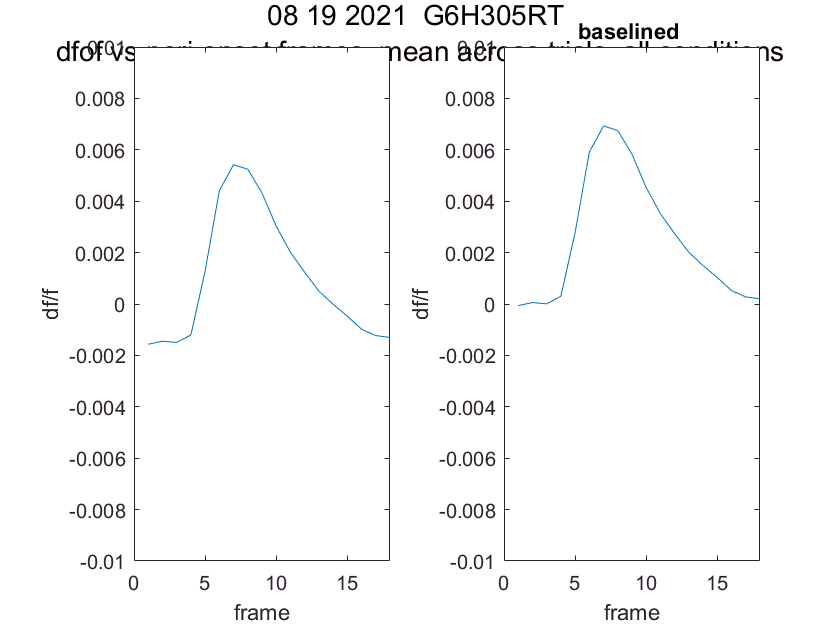

% now do similar - show that subtracting mean basline values works as expected, but
% plot mean (over trials) df of entire (cropped) imageing view vs frames (regular graph, not pixel wise)
plotPrePostBaselineOnsetDfVsFrames(onsetDf,date,subjName,baselineIdx);

% define peak activity frames (can change num frames in code, default is 10 frames post-stim onset frame)
[peakFrameIdx] = pickPeakFrames(stimOnsetFrame);

stimOnsetFrame =      4


peakFrameIdx =      5     6     7     8     9    10    11    12    13    14


% pix wise peri stim  per stim cond (con only then dur only)

% DO in COMMAND LINE
showPixWiseByStimConds(stimOnsetFrame,date,subjName,uniqueContrasts,conOrderedByTrialMeetCriteria,onsetDf,baselineIdx,uniqueDurations,durOrderedByTrialMeetCriteria);

% show peak pix wise activity for each stim condition (con/dur combo)

% PROBLEM using this in live script.. it only shows the figure at the end so I can't adjust the range
showPixWisePeakActivityPerStimCond(date,subjName,uniqueContrasts,uniqueDurations,conAndDurOrderedByTrialMeetCriteria,peakFrameIdx,onsetDf,baselineIdx);

% Pick the image to be used to pick points in visual areas in next step

% PROBLem w/range part, use command line if want
[baselinedActIm,range] = pickPeakActIm4Points(conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations,peakFrameIdx,onsetDf,baselineIdx);

% % Make 3 IMAGE to help idenitfy visual areas & blood vessels...
% % first run do_topo, which needs the recording session to be un-commented in batch file
%[meanpolar,ypts,xpts] = do_topo();

% % now SHOW the fig (despite that the name of the function says)
% % CHANGE the tif file/folder path in ehere each time
% pickVisAreaPts3figs(meanpolar,ypts,xpts,baselinedActIm,range);

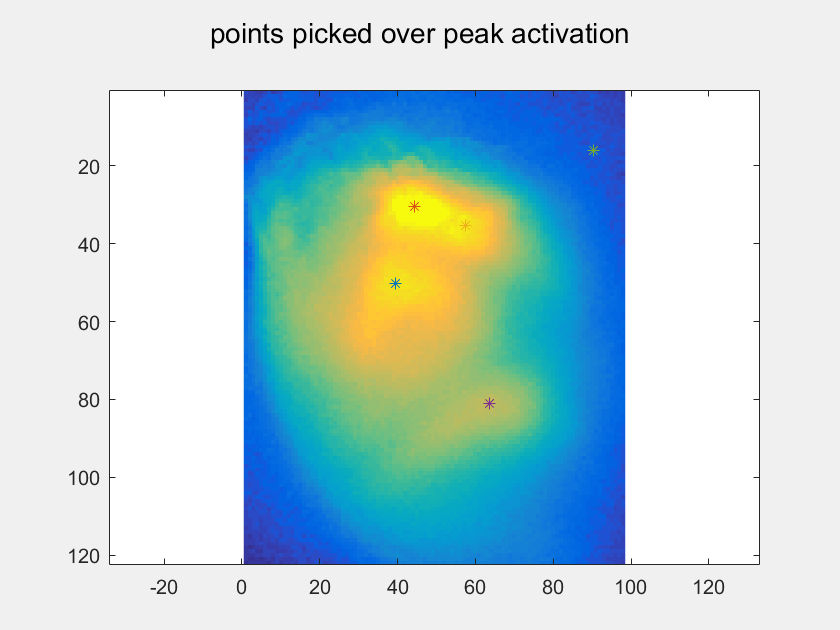

% actually pick the points
[xPickedPts,yPickedPts] = pickVisAreaPts(baselinedActIm,range,colorMapOrNot);

% make PTSdfof - this time I took the *mean over 5 pixels* for each point
[RoundXpts,RoundYpts,PTSdfof] = makePTSdfof(xPickedPts,yPickedPts,onsetDf,range,colorMapOrNot);

sizePTSdfof =            5          18        1229


% SAVE VARS FOR REST OF ANALYSIS

% ** NAVIGATE to correct folder **

% save('v2_081921_G6H305RT_vars4IndAndGroupAnalyses.mat',...
%     'stimDetails','subjData','trialCond','subjName','date',...
%     'frameT','numPreStimFrames','numPostStimFrames','onsetDf',...
%     'idxOnsetsMeetsCriteria','peakFrameIdx','stimOnsetFrame','baselineIdx',...
%     'baselinedActIm','xPickedPts','yPickedPts','RoundXpts','RoundYpts',...
%     'PTSdfof','meanSpeedAllTrials','idxRunTrials','idxStatTrials','-v7.3') % '-append',